Author：黃仕鈞

# Autoregressive Modeling

clear all; clc;

# Initial parameter

## Sampling parameters

$\mathrm{Samples}\;\mathrm{quantity}$, N = 100

N = 100; % quantity of samples

## Gaussian noise


$$e_n \;=\mathrm{randn}\left(N\right)$$


e = randn(N);
e = e / max(e);

# AR(p), Control lag

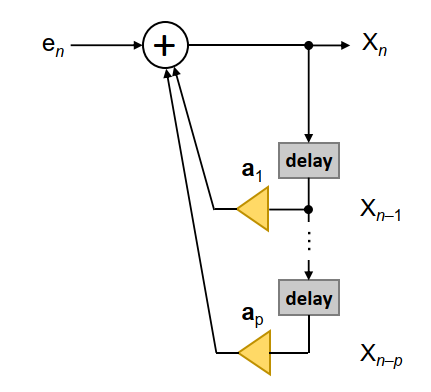


$$X_n =c+\sum_{i=1}^p a_i X_{n-i} +e_n$$


透過改變$a_i$增益來做，AR(1)，表示找前一個採樣 $X_{n-i}$與一個增益$a_i$乘得到結果, delay 1 sampe。

[Autoregressive for forecast error](https://youtu.be/4WWQWeMXvas): Youtube

delay 不能超過sample數量

Only for short-term forecasts

To forcast k-steps ahead($$$\mathrm{F}_{\mathrm{t}+\mathrm{k}}$$$)

Use AR(p) model only if k>p, p  lag p sequence, k is steps

clear all; close all; clc;
% parameter
N = 100; % quantity of samples
e = randn(N);
e = e / max(e);

% es = sin((1:N))+ sin((1:N).*2+10); % add sin sin wave
% e = 1./6.*(es'+e); % es' is transpose result of es

a = [];
lag = 50; % AR(p) p is lag
% (N-lag)>=2 need to be true(==1), '>1' -> lag ,'>2' integral
a = zeros(1,lag);
ac = zeros(1,lag);

% time varying a --> design varying a
for i = 1:N
    a(i) = (i/N);
end

% ac = [0.1, 0.9, -0.9 ,0.3, 0.5]; % constant close to 0, 1...
k = randn(lag);
ac = k / max(k);  % random a [-1,1]

x = zeros(1,N);
xc = zeros(1,N); % 初始化矩陣大小 constant

for i =1:lag % lag not calc
    x(i) = e(i); % a(i).*x(j,i)+e(j);
    xc(i) = e(i); % ac(i).*x(j,i)+e(j);
end

for i = (1+lag):N % calc start from AR(p->lag) --> lag+2
    ax_poly = zeros(1,lag);
    axc_poly = zeros(1,lag);
    for k =1:lag % ex: a1.*x_{3-lag}+ a2.*x_{3-lag}, lag =2
        ax_poly(k) = a(k).*x(i-lag);
        axc_poly(k) = ac(k).*x(i-lag);
    end
    x(i) =sum(ax_poly)+e(i);
    xc(i) = sum(axc_poly)+e(i); % 對照組 constant a
    g_struct = struct('lag_p',lag,'samples',N, 'varing_gain',a,...
        'predict',x(:,1),'noise',(e.*0.9), 'input',e );
end

# Plot

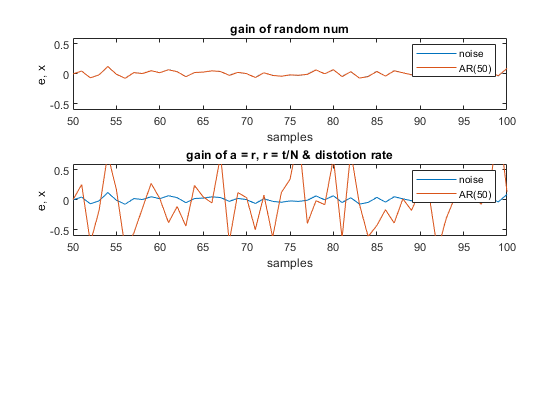

% Plot
% print the distortion rate of x(lag:N) t in [lag, N]
str1 = ['AR', '(', string(lag), ')' ];
t = linspace(1,N,N);
ylimit_const = [-0.6, 0.6];
AR = sprintf( str1(1)+str1(2)+str1(3)+str1(4));

figure();
subplot(3, 1, 1);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end));
title('gain of random num');
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 2);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),x(lag:end));
title('gain of a = r, r = t/N & distotion rate')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)

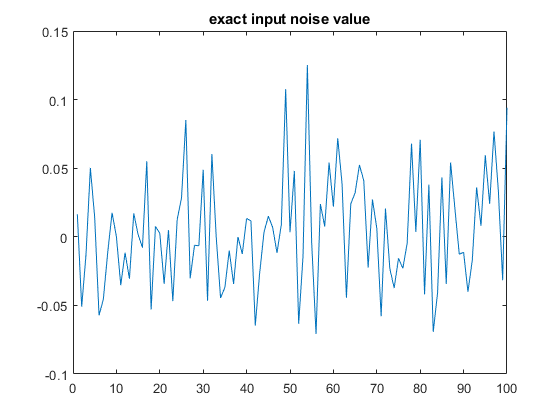

figure(); plot(t,e);title('exact input noise value')